a = imread("cat.jpg");
whos("a")

  Name        Size                Bytes  Class    Attributes

  a         480x640x3            921600  uint8              



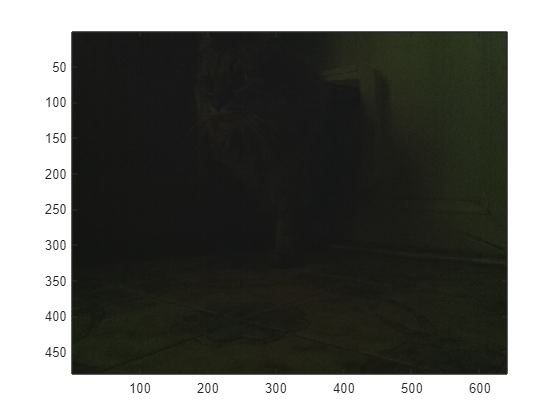

figure(1); image(a); s =size(a);

%Planos

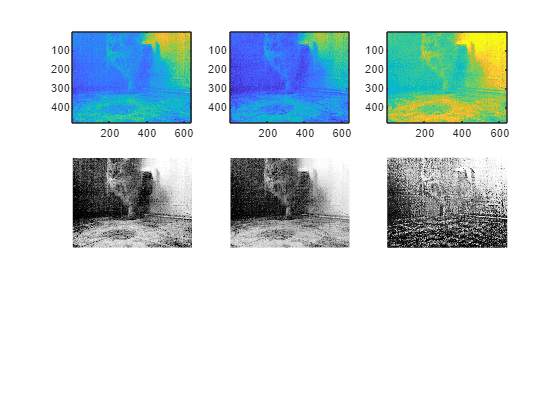

%Planos Normalizados
ar = a(:,:,1); ar = double(ar); ar = ar/255;
ag = a(:,:,2); ag = double(ag); ag = ag/255;
ab = a(:,:,3); ab = double(ab); ab = ab/255;

%Procesamiento 
gamma = 0.2;
gam_ar = ar.^gamma; gam_ar = gam_ar*255;
gam_ag = ag.^gamma; gam_ag = gam_ag*255;
gam_ab = ab.^gamma; gam_ab = gam_ab*255;


% Histogram Streching
% gam_ar = double(gam_ar);
st_gam_ar = (gam_ar-min(gam_ar(:)))/(max(gam_ar(:))-min(gam_ar(:)))*255;
st_gam_ag = (gam_ar-min(gam_ag(:)))/(max(gam_ag(:))-min(gam_ag(:)))*255;
st_gam_ab = (gam_ar-min(gam_ab(:)))/(max(gam_ab(:))-min(gam_ab(:)))*255;

figure(2);subplot(3,3,1); image(st_gam_ar);
figure(2);subplot(3,3,2); image(st_gam_ag);
figure(2);subplot(3,3,3); image(st_gam_ab);
figure(2);subplot(3,3,4); imhist(st_gam_ag);
figure(2);subplot(3,3,5); histeq(ag);
figure(2);subplot(3,3,6); histeq(ab);

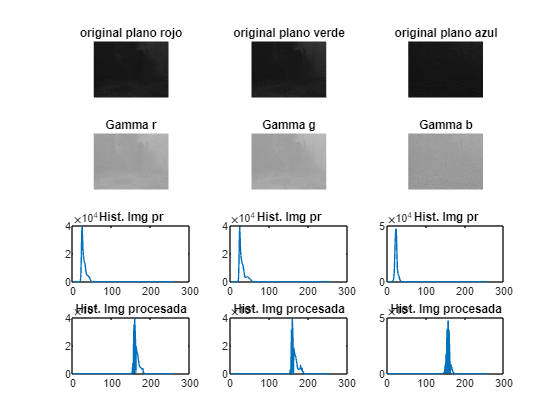


%Despues
%Denormalizacion
%Valore enteros de 8 bits sin signo -uint8
gam_ar = uint8(gam_ar); ar = ar*255; ar = uint8(ar);
gam_ag = uint8(gam_ag); ag = ag*255; ag = uint8(ag);
gam_ab = uint8(gam_ab); ab = ab*255; ab = uint8(ab);

figure(3);
subplot(4,3,1);imshow(ar);title('original plano rojo');
subplot(4,3,2);imshow(ag);title('original plano verde');
subplot(4,3,3);imshow(ab);title('original plano azul');
subplot(4,3,4);imshow(gam_ar);title('Gamma r');
subplot(4,3,5);imshow(gam_ag);title('Gamma g');
subplot(4,3,6);imshow(gam_ab);title('Gamma b');

histR = zeros(1,256); histar_g = zeros(1,256);
histG = zeros(1,256); histag_g = zeros(1,256);
histB = zeros(1,256); histab_g = zeros(1,256);
for f = 1:s(1)
    for c = 1:s(2)
        ngR = ar(f,c);
        histR(ngR + 1) = histR(ngR + 1) + 1;
        nr = gam_ar(f,c);
        histar_g(nr + 1) = histar_g(nr + 1) + 1;

        ngG = ag(f,c);
        histG(ngG + 1) = histG(ngG + 1) + 1;
        ng = gam_ag(f,c);
        histag_g(ng + 1) = histag_g(ng + 1) + 1;
        

        ngB = ab(f,c);
        histB(ngB + 1) = histB(ngB + 1) + 1;
        nb = gam_ab(f,c);
        histab_g(nb + 1) = histab_g(nb + 1) + 1;
    end
end
%visualozar histograma
figure(3);
subplot(4,3,7);plot(histR); title("Hist. Img pr");
subplot(4,3,8);plot(histG); title("Hist. Img pr");
subplot(4,3,9);plot(histB); title("Hist. Img pr");
subplot(4,3,10);plot(histar_g); title("Hist. Img procesada");
subplot(4,3,11);plot(histag_g); title("Hist. Img procesada");
subplot(4,3,12);plot(histab_g); title("Hist. Img procesada");